# HW5 Program Assignment

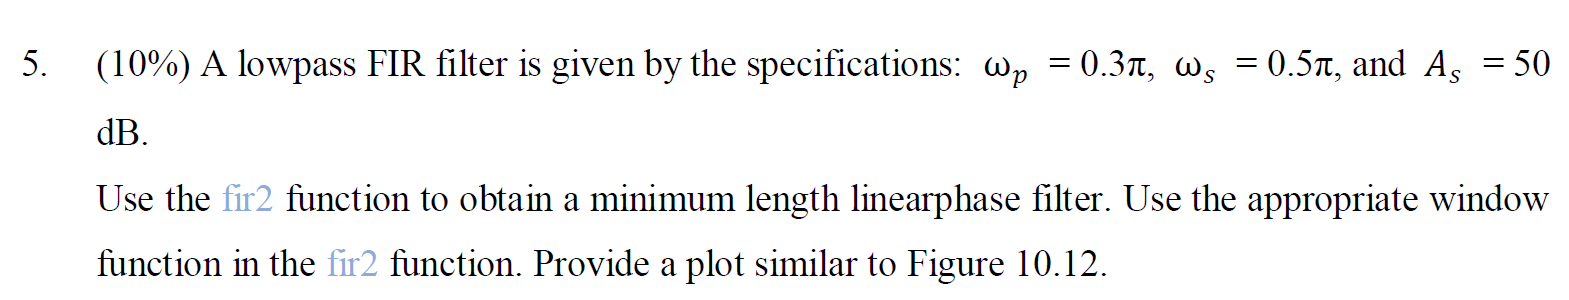

### 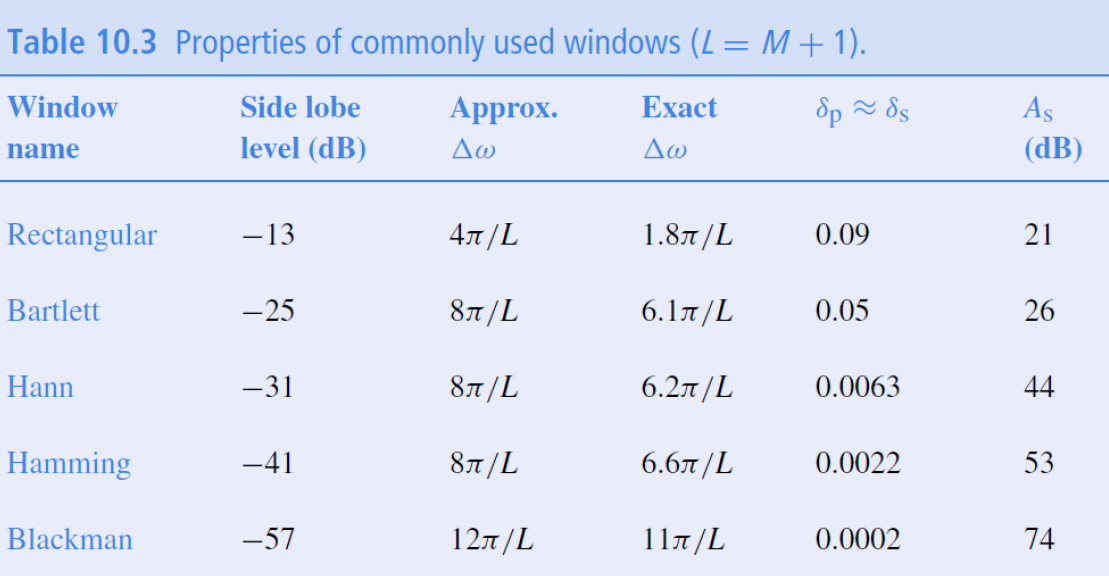

### According to this table and $A_s =50\;\mathrm{dB}$, we should choose Hamming window.

$\Delta \omega =0\ldotp 5\pi -0\ldotp 3\pi =0\ldotp 2\pi \Longrightarrow 6\ldotp 6\frac{\pi }{L}\le 0\ldotp 2\pi \Longrightarrow L\ge 33$ (also type I)


$$\omega_c =\frac{0\ldotp 5\pi +0\ldotp 3\pi }{2}=0\ldotp 4\pi$$


But if using this value (M) to design, $A_s$ wouldn't meet the standard. Therefore, I increased the length to L+4.

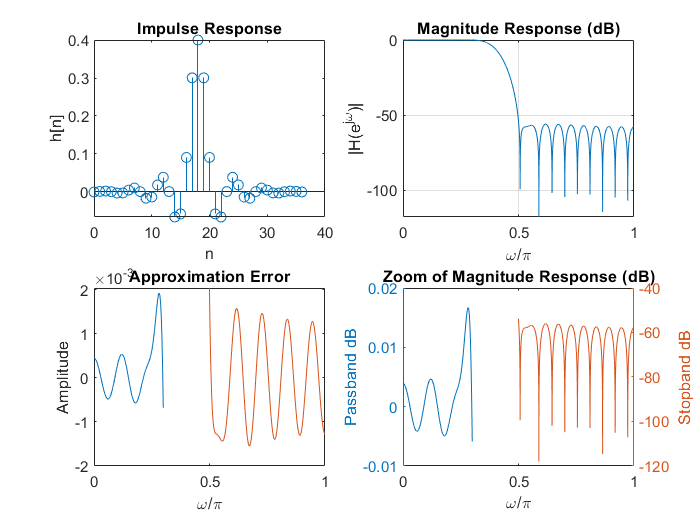

f = [0 0.4 0.4 1];  %normalized frequency 0 ~ pi first element of f is 0, last one is 1
A = [1 1 0 0]; % magnitude response at each frequency of f
M = 33-1; %length-1
point = 4000;
ham = fir2(M+4, f, A); %default hamming window
[H, w] = freqz(ham, [1], point);
figure;
subplot 221
stem(0:M+4, ham); 
title('Impulse Response');
xlabel('n');
ylabel('h[n]');
subplot 222
plot(w/pi, 20*log10(abs(H)));
grid on
title('Magnitude Response (dB)');
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');
subplot 223
H_amp = zerophase(ham, 1, point);
pass = 1:0.3*point; % pass band
stop = 0.5*point:point;% stop band
plot(w(pass)/pi, H_amp(pass)-1);
hold on
plot(w(stop)/pi, H_amp(stop));
hold off
title('Approximation Error');
xlabel('\omega/\pi');
ylabel('Amplitude');
subplot 224
yyaxis left
plot(w(pass)/pi,  20*log10(abs(H(pass))));
title('Zoom of Magnitude Response (dB)');
xlabel('\omega/\pi');
ylabel('Passband dB');
hold on
yyaxis right
plot(w(stop)/pi,  20*log10(abs(H(stop))));
ylabel('Stopband dB');
hold off

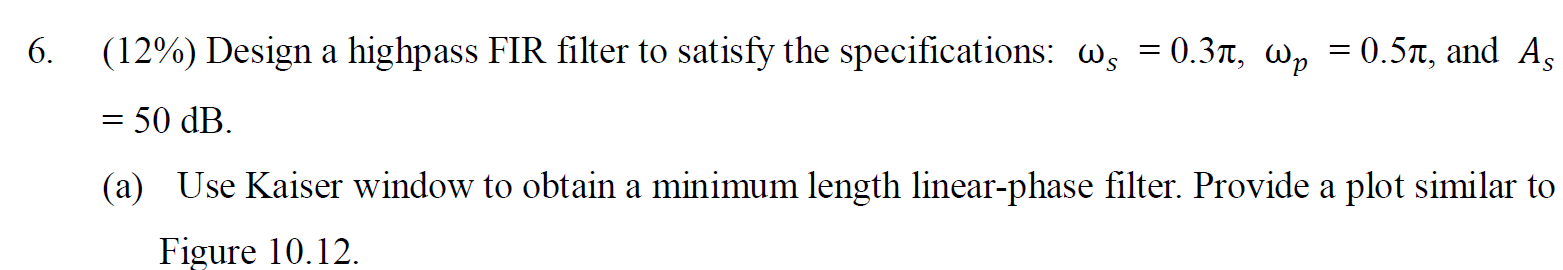

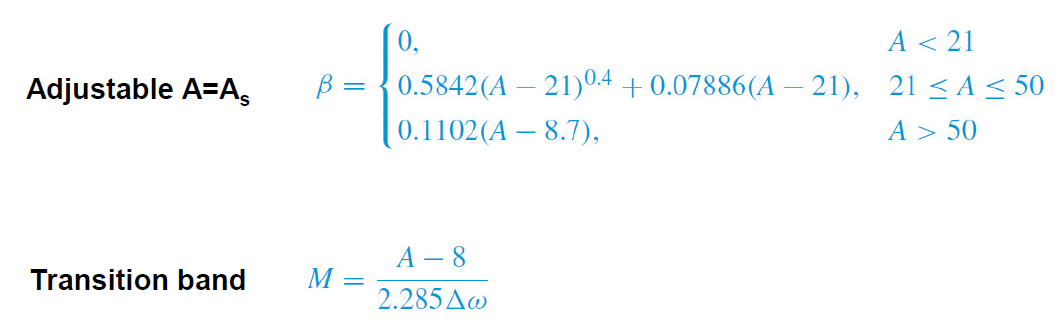

### A = 50 ->$\begin{array}{l}
\;\\
M=\frac{42}{2\ldotp 285\times 0\ldotp 2\pi }=29\ldotp 25\to \textrm{So}\;\textrm{we}\;\textrm{take}\;M=30\to \;L\;=\;31\ldotp 
\end{array}$

### 
$$\omega_c =\frac{0\ldotp 3\pi +0\ldotp 5\pi }{2}=0\ldotp 4\pi$$
      

But if using this value (M) to design, $A_s$ wouldn't meet the standard. Therefore, I increased the length to L+2.

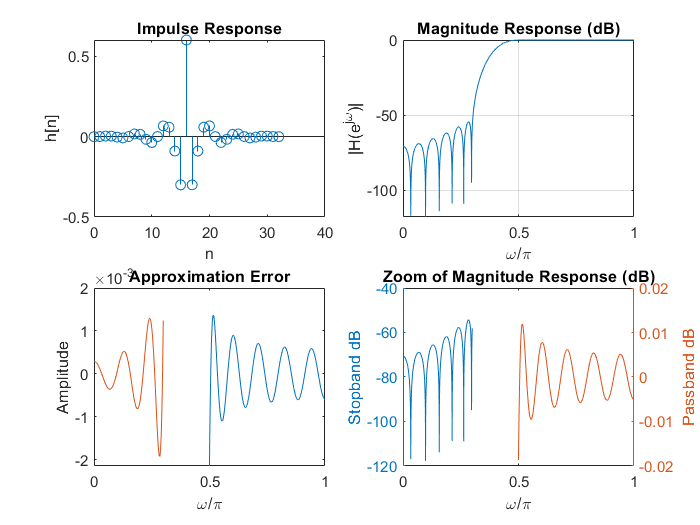

M = 30;
L = M+1;
A = 50;
beta = 0.5842*(A - 21)^0.4 + 0.07886*(A - 21);
window = kaiser(L+2, beta);%w = kaiser(L,beta) returns an L-point Kaiser window with shape factor beta.
f = [0 0.4 0.4 1];  %normalized frequency 0 ~ pi first element of f is 0, last one is 1
A = [0 0 1 1]; % magnitude response at each frequency of f
h_a = fir2(M+2, f, A, window);
[H, w] = freqz(h_a, [1], point);
figure;
subplot 221
stem(0:M+2, h_a);  
title('Impulse Response');
xlabel('n');
ylabel('h[n]');
subplot 222
plot(w/pi, 20*log10(abs(H)));
grid on
title('Magnitude Response (dB)');
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');
subplot 223
pass = 0.5*point:point;
stop = 1:0.3*point;
H_amp = zerophase(h_a, 1, point);
plot(w(pass)/pi, H_amp(pass)-1);
hold on
plot(w(stop)/pi, H_amp(stop));
hold off
title('Approximation Error');
xlabel('\omega/\pi');
ylabel('Amplitude');
subplot 224
yyaxis right
plot(w(pass)/pi,  20*log10(abs(H(pass))));
title('Zoom of Magnitude Response (dB)');
xlabel('\omega/\pi');
ylabel('Passband dB');
hold on
yyaxis left
plot(w(stop)/pi,  20*log10(abs(H(stop))));
ylabel('Stopband dB');
hold off

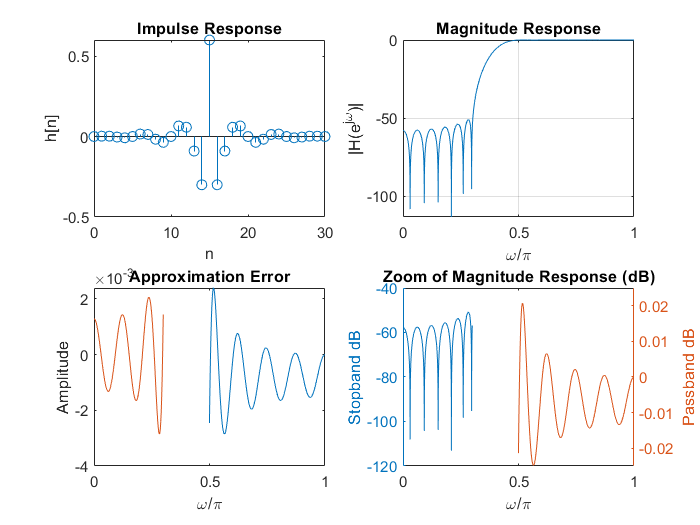

M = 30;
L = M+1;
A = 50;
beta = 0.5842*(A - 21)^0.4 + 0.07886*(A - 21);
window = kaiser(L, beta);
h_b = fir1(M, 0.4, 'high', window); % cutoff frequency = 0.4*pi
[H, w] = freqz(h_b, [1], point);
figure;
subplot 221;
stem(0:M, h_b);
title('Impulse Response');
xlabel('n');
ylabel('h[n]');
subplot 222
plot(w/pi, 20*log10(abs(H)));
title('Magnitude Response');
grid on
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');
subplot 223
H_amp = zerophase(h_b, 1, point);
pass = 0.5*point:point;
stop = 1:0.3*point;
plot(w(pass)/pi, H_amp(pass)-1);
hold on
plot(w(stop)/pi, H_amp(stop));
hold off
title('Approximation Error');
xlabel('\omega/\pi');
ylabel('Amplitude');
subplot 224
yyaxis right
plot(w(pass)/pi,  20*log10(abs(H(pass))));
title('Zoom of Magnitude Response (dB)');
xlabel('\omega/\pi');
ylabel('Passband dB');
hold on
yyaxis left
plot(w(stop)/pi,  20*log10(abs(H(stop))));
ylabel('Stopband dB');
hold off

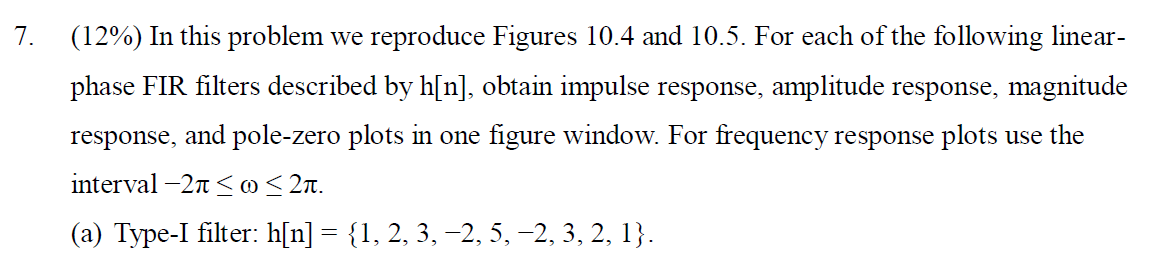

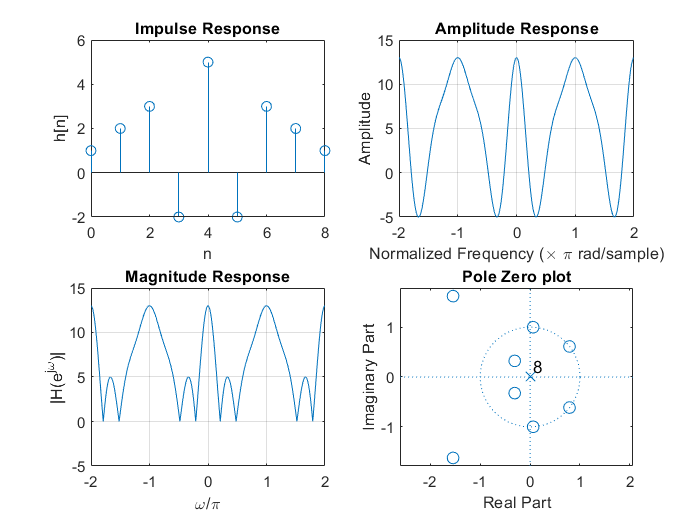

h_a = [1 2 3 -2 5 -2 3 2 1];
M = 8;
figure;
subplot 221
stem(0:M, h_a);
title('Impulse Response')
xlabel('n');
ylabel('h[n]');
subplot 222;
zerophase(h_a, 1, linspace(-2*pi, 2*pi, point)); 
title('Amplitude Response');
subplot 223
[H_a, w] = freqz(h_a, [1], linspace(-2*pi, 2*pi, point));
plot(w/pi, abs(H_a));
grid on
ylim([-5, 15]);
title('Magnitude Response')
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');
subplot 224
zplane(h_a, 1);
title('Pole Zero plot');

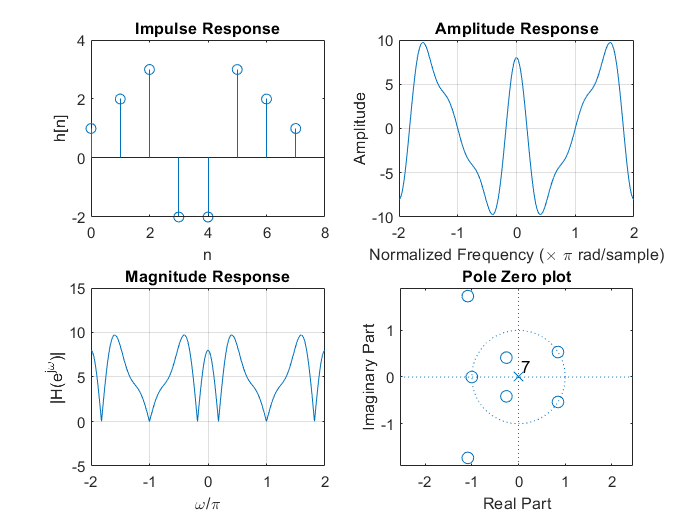

h_b = [1 2 3 -2 -2 3 2 1];
M = 7;
figure;
subplot 221
stem(0:M, h_b);
title('Impulse Response')
xlabel('n');
ylabel('h[n]');
subplot 222;
zerophase(h_b, 1, linspace(-2*pi, 2*pi, point));  
title('Amplitude Response');
subplot 223
[H_b, w] = freqz(h_b, [1], linspace(-2*pi, 2*pi, point));
plot(w/pi, abs(H_b));
grid on
ylim([-5, 15]);
title('Magnitude Response')
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');
subplot 224
zplane(h_b, 1);
title('Pole Zero plot');

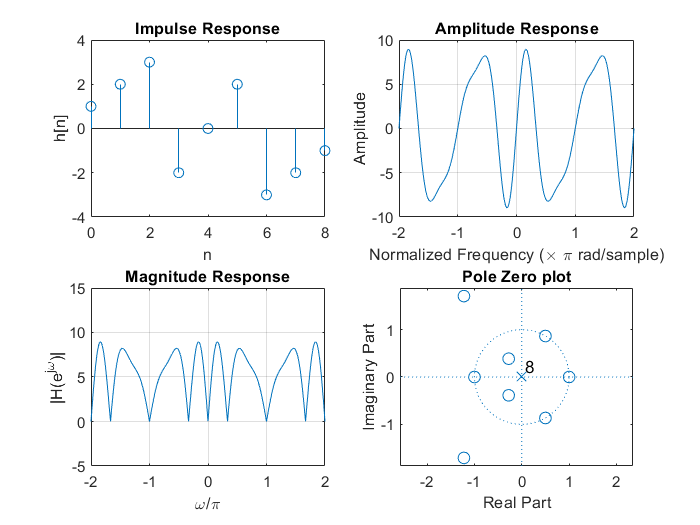

h_c = [1 2 3 -2 0 2 -3 -2 -1];
M = 8;
figure;
subplot 221
stem(0:M, h_c);
title('Impulse Response')
xlabel('n');
ylabel('h[n]');
subplot 222;
zerophase(h_c, 1, linspace(-2*pi, 2*pi, point));  
title('Amplitude Response');
subplot 223
[H_c, w] = freqz(h_c, [1], linspace(-2*pi, 2*pi, point));
plot(w/pi, abs(H_c));
grid on
ylim([-5, 15]);
title('Magnitude Response')
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');
subplot 224
zplane(h_c, 1);
title('Pole Zero plot');

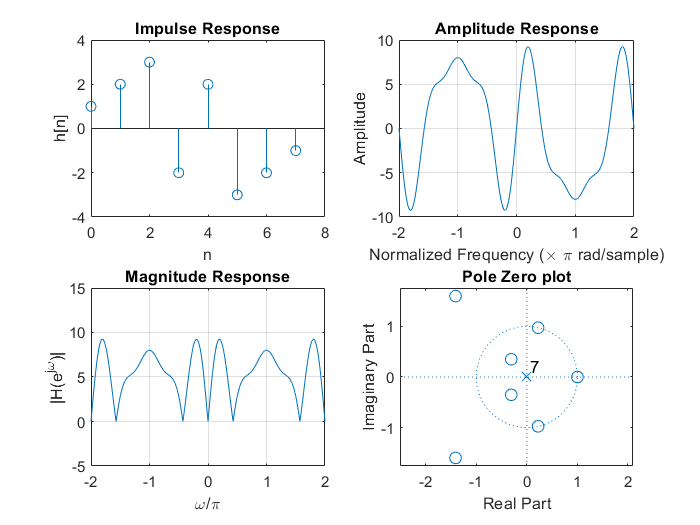

h_d = [1 2 3 -2  2 -3 -2 -1];
M = 7;
figure;
subplot 221
stem(0:M, h_d);
title('Impulse Response')
xlabel('n');
ylabel('h[n]');
subplot 222;
zerophase(h_d, 1, linspace(-2*pi, 2*pi, point));  
title('Amplitude Response');
subplot 223
[H_d, w] = freqz(h_d, [1], linspace(-2*pi, 2*pi, point));
plot(w/pi, abs(H_d));
grid on
ylim([-5, 15]);
title('Magnitude Response')
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');
subplot 224
zplane(h_d, 1);
title('Pole Zero plot');

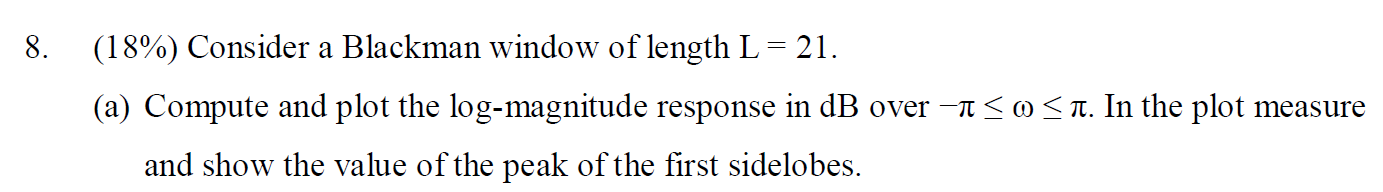

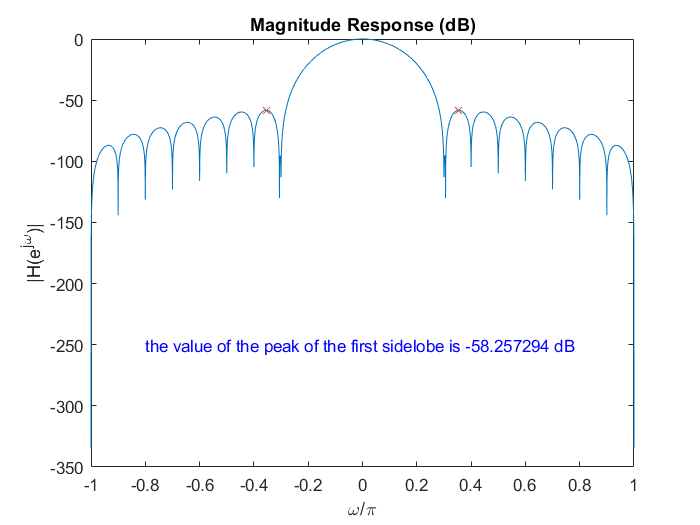

L = 21;
h_a = blackman(L);
[H_a, w] = freqz(h_a, [1], linspace(-pi, pi, point));
figure;
norm = 20*log10(abs(H_a)) - max(20*log10(abs(H_a)));  % normalize
[pks,locs] = findpeaks(norm,w,'SortStr','descend');
plot(w/pi, norm);
text(-0.8, -250, sprintf('the value of the peak of the first sidelobe is %f dB', pks(2)),'FontSize',10, 'color', 'blue');
hold on
plot(locs(2:3)/pi, pks(2:3), 'x');
hold off
title('Magnitude Response (dB)');
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');

### Hence, the value of the peak of the first sidelobe is -58.259393dB.

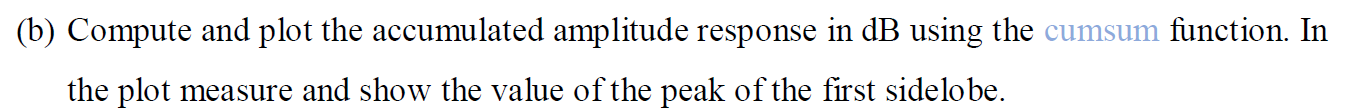

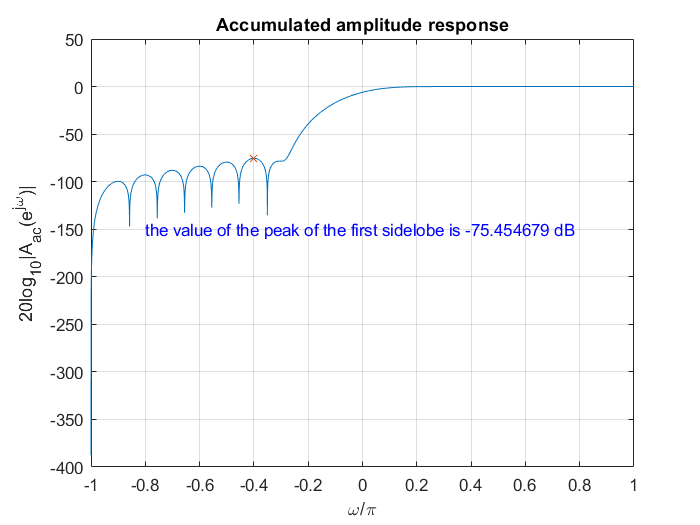

x = linspace(-pi, pi, point);
A = zerophase(h_a, 1, x);
figure;
plot(x/pi, 20*log10(abs(cumsum(A)/sum(A))));  % divided by sum(A) to normalize
grid on
[pks,locs] = findpeaks(20*log10(abs(cumsum(A)/sum(A))),x,'SortStr','descend');
idx = find(pks < -50);
text(-0.8, -150, sprintf('the value of the peak of the first sidelobe is %f dB', pks(idx(1))),'FontSize',10, 'color', 'blue');
hold on
plot(locs(idx(1))/pi, pks(idx(1)), 'x');
hold off
title('Accumulated amplitude response');
xlabel('\omega/\pi');
ylabel('20log_{10}|A_{ac}(e^{j\omega})|');  

### Hence, the value of the peak of the first sidelobe is -75dB.

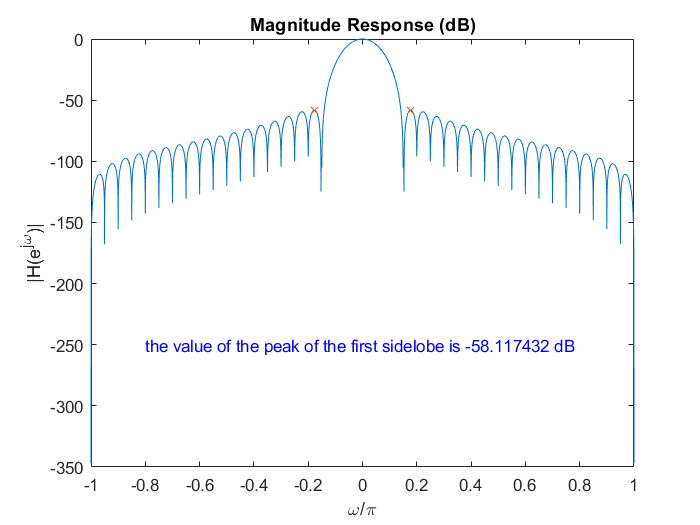

L = 41;
h_a = blackman(L);
[H_a, w] = freqz(h_a, [1], linspace(-pi, pi, point));
figure;
norm = 20*log10(abs(H_a)) - max(20*log10(abs(H_a)));  % normalize
[pks,locs] = findpeaks(norm, w, 'SortStr','descend');
plot(w/pi, norm);
text(-0.8, -250, sprintf('the value of the peak of the first sidelobe is %f dB', pks(2)),'FontSize',10, 'color', 'blue');
hold on
plot(locs(2:3)/pi, pks(2:3), 'x');
hold off
title('Magnitude Response (dB)');
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');

### Hence, the value of the peak of the first sidelobe is -58.116430dB

Repeat (b)  

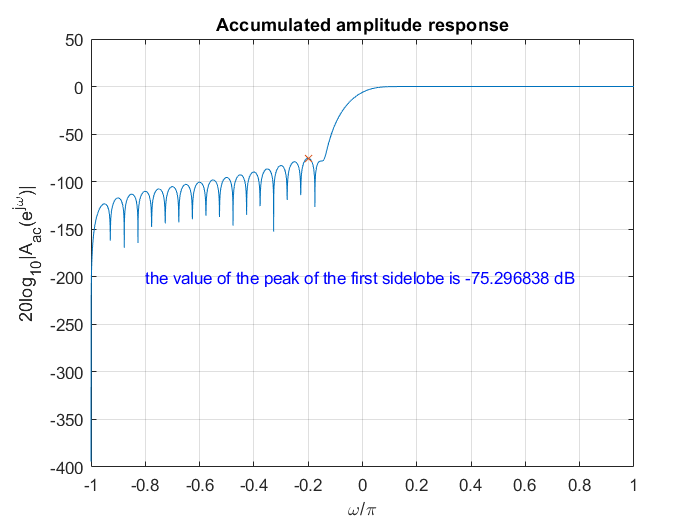

x = linspace(-pi, pi, point);
A = zerophase(h_a, 1, x);
figure;
plot(x/pi, 20*log10(abs(cumsum(A)/sum(A)))); % divide by sum(A) to normalize
grid on
[pks,locs] = findpeaks(20*log10(abs(cumsum(A)/sum(A))),x,'SortStr','descend');  % divide by sum(A) to normalize
idx = find(pks < -50);
text(-0.8, -200, sprintf('the value of the peak of the first sidelobe is %f dB', pks(idx(1))),'FontSize',10, 'color', 'blue');
hold on
plot(locs(idx(1))/pi, pks(idx(1)), 'x');
hold off
title('Accumulated amplitude response');
xlabel('\omega/\pi');
ylabel('20log_{10}|A_{ac}(e^{j\omega})|');  

### Hence, the value of the peak of the first sidelobe is -58.116430dB

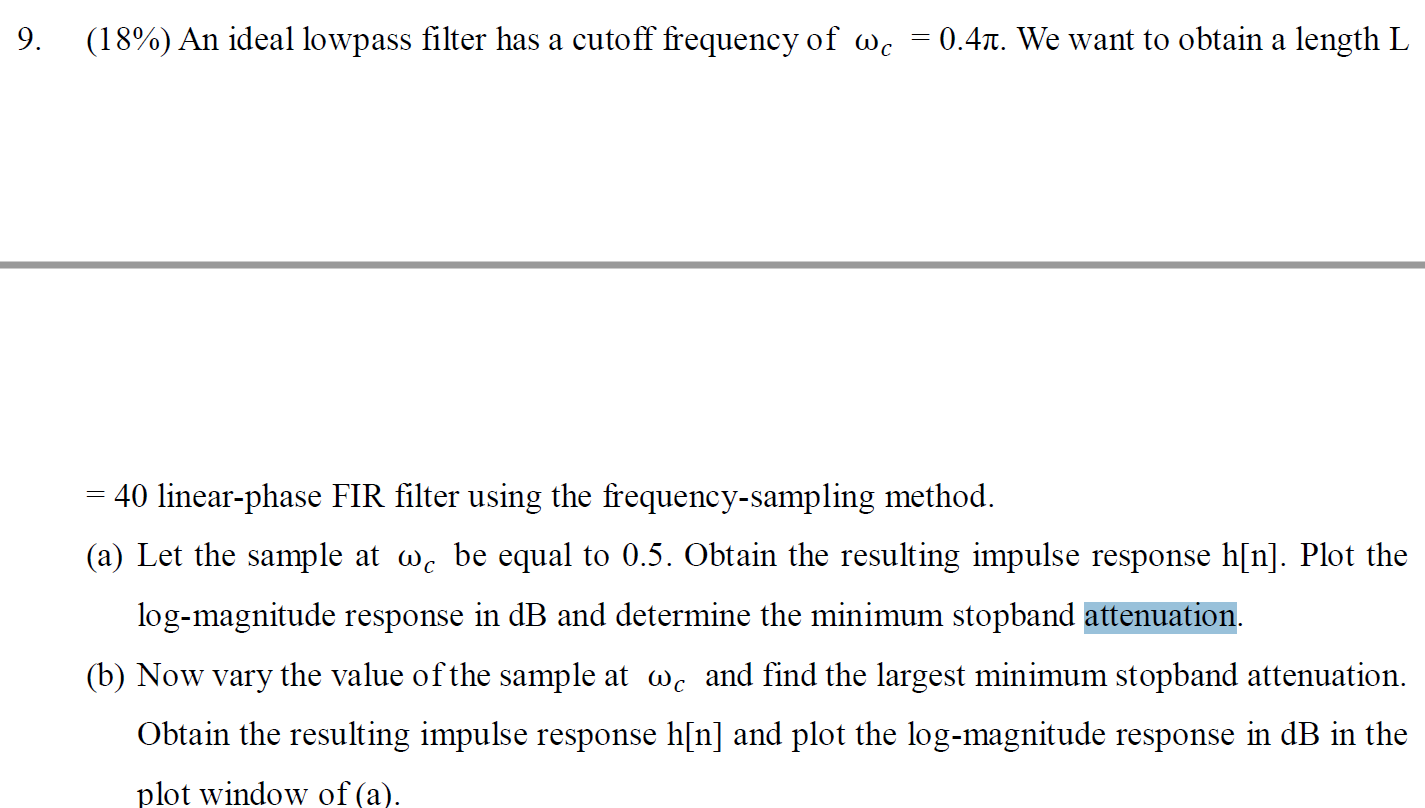

M = 39; L = M+1;                           % Impulse response length
alpha = M/2; Q = floor(alpha);             % phase delay parameters
om = linspace(0,2*pi,1001);                  % Frequency array
k = 0:M;                                   % Frequency sample index
psid = -alpha*2*pi/L*[(0:Q),-(L-(Q+1:M))]; % Desired Phase
Dw = 2*pi/L;                               % Width between frequency samples
% Design
omc = 0.4*pi;                                              % Cutoff frequency
k1 = floor(omc/Dw);                                        % Left sample index nearest to cutoff edge
k2 = ceil(omc/Dw);                                         % Right sample index nearest to cutoff edge
Ad = [ones(1,k1), 0.5, zeros(1,L-2*k2-2), 0.5, ones(1, k1)];          % Desired Amplitude
Hd = Ad.*exp(1j*psid);                                     % Desired Freq Resp Samples
hd = real(ifft(Hd));                                       % Desired Impulse response
h_a = hd.*hamming(L)';                                       % Hamming window Impulse response
[H_a, w] = freqz(h_a,1,om);                                     % Frequency response of the actual filter
figure;
p1 = plot(w(1:500)/pi, 20*log10(abs(H_a(1:500))));
grid on
xlabel('\omega/\pi');
ylabel('Magnitude (dB)');
title('Magnitude Response (dB)');
[pks,locs] = findpeaks(20*log10(abs(H_a(1:500))), w(1:500)/pi,'SortStr','descend');
hold on
plot(locs(4), pks(4), 'x');
text(0.1, -160, sprintf('the minimum stopband attenuation is %f dB (part a)', pks(4)),'FontSize',10, 'color', 'blue');
hold off


As part (c) requires us to apply hamming window, I also used hamming window here for comparison.

And for part (b), to find the largest minumum stopband attenuation (i.e. maximize the sidelobe), I found the sidelobe would decrease the stop band ripple when value of the sample at $\omega_c$ less than 0.5. 

I found the lergest minimum stopband attenuation when the value of the sample at  $\omega_C$ is about 0.1.

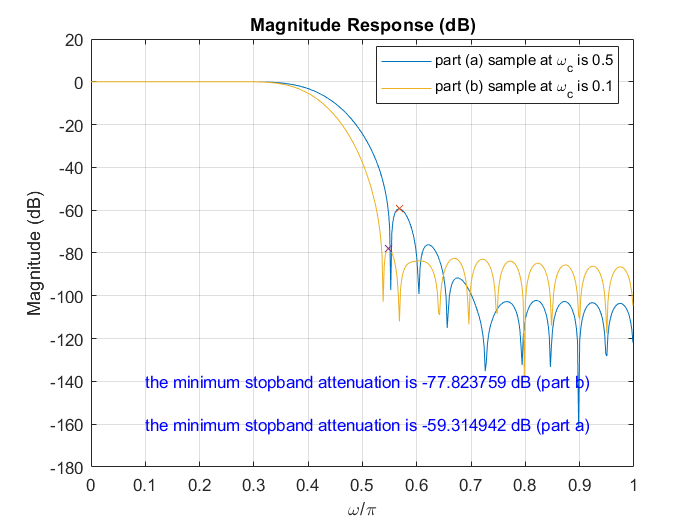


% ================================== (b)==================================

hold on
sample_at_omc = 0.1;  % To increase the sidelobe, I need to decrease the mainlobe
Ad = [ones(1,k1), sample_at_omc, zeros(1,L-2*k2-2), sample_at_omc, ones(1, k1)];          % Desired Amplitude
Hd = Ad.*exp(1j*psid);                                     % Desired Freq Resp Samples
hd = real(ifft(Hd));                                       % Desired Impulse response
h_b = hd.*hamming(L)';                                       % Hamming window Impulse response
[H_b, w] = freqz(h_b,1,om);                                     % Frequency response of the actual filter
p2 = plot(w(1:500)/pi, 20*log10(abs(H_b(1:500))));
grid on
xlabel('\omega/\pi');
ylabel('Magnitude (dB)');
title('Magnitude Response (dB)');
[pks,locs] = findpeaks(20*log10(abs(H_b(1:500))), w(1:500)/pi,'SortStr','descend');
hold on
plot(locs(4), pks(4), 'x');
text(0.1, -140, sprintf('the minimum stopband attenuation is %f dB (part b)', pks(4)),'FontSize',10, 'color', 'blue');
hold off
legend([p1, p2], {'part (a) sample at \omega_{c} is 0.5', 'part (b) sample at \omega_{c} is 0.1'}, 'Location', 'best');

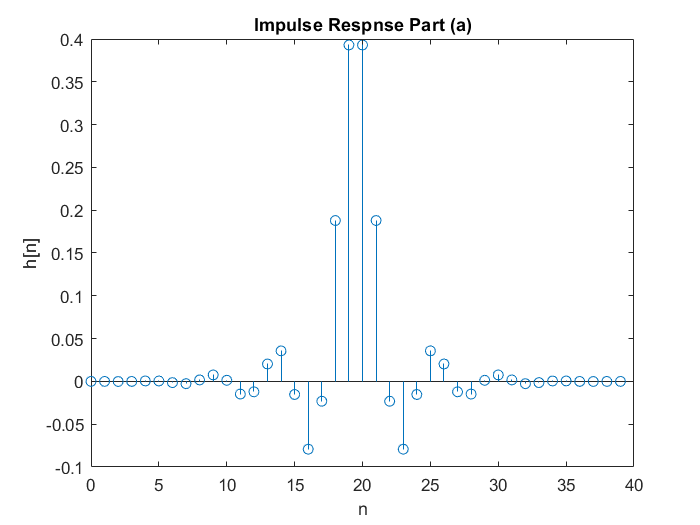

figure;
stem(0:M, h_a);
xlabel('n');
ylabel('h[n]');
title('Impulse Respnse Part (a)');

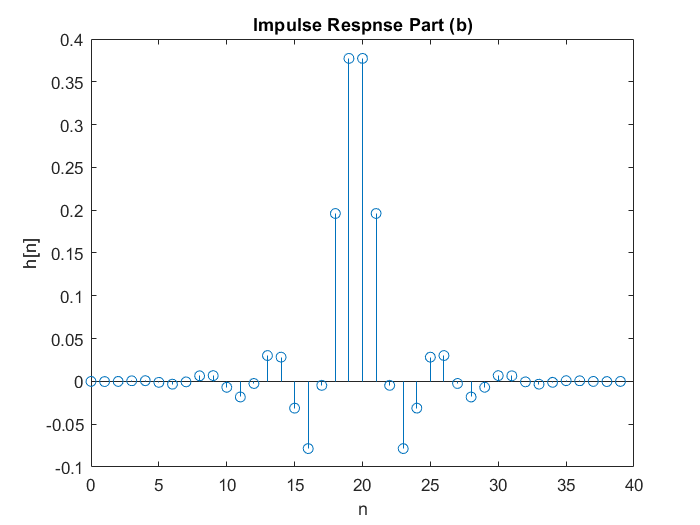

figure;
stem(0:M, h_b);
xlabel('n');
ylabel('h[n]');
title('Impulse Respnse Part (b)');

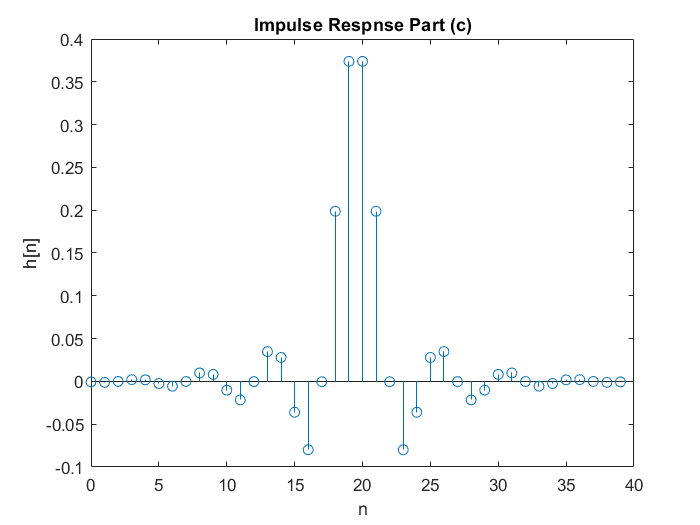

f = [0 0.4 0.4 1];                     %normalized frequency 0 ~ pi first element of f is 0, last one is 1
A = [1 1 0 0];                         % magnitude response at each frequency of f
M = 39; L = M+1;                      
h_c = fir2(M, f, A);                   %default hamming window
[H_c, w] = freqz(h_c, [1], 500);
figure;
stem(0:M, h_c);
xlabel('n');
ylabel('h[n]');
title('Impulse Respnse Part (c)');

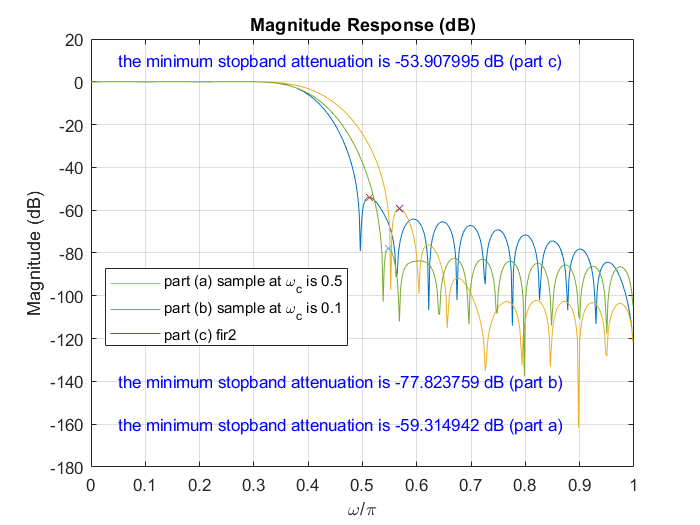

figure;
p3 = plot(w(1:500)/pi, 20*log10(abs(H_c)));
[pks,locs] = findpeaks(20*log10(abs(H_c)), w(1:500)/pi,'SortStr','descend');
hold on
plot(locs(4), pks(4), 'x');
text(0.05, 10, sprintf('the minimum stopband attenuation is %f dB (part c)', pks(4)),'FontSize',10, 'color', 'blue');


p1 = plot(w(1:500)/pi, 20*log10(abs(H_a(1:500))));
[pks,locs] = findpeaks(20*log10(abs(H_a(1:500))), w(1:500)/pi,'SortStr','descend');



plot(locs(4), pks(4), 'x');
text(0.05, -160, sprintf('the minimum stopband attenuation is %f dB (part a)', pks(4)),'FontSize',10, 'color', 'blue');

grid on 
xlabel('\omega/\pi');
ylabel('Magnitude (dB)');
title('Magnitude Response (dB)');

p2 = plot(w(1:500)/pi, 20*log10(abs(H_b(1:500))));
grid on
xlabel('\omega/\pi');
ylabel('Magnitude (dB)');
title('Magnitude Response (dB)');
[pks,locs] = findpeaks(20*log10(abs(H_b(1:500))), w(1:500)/pi,'SortStr','descend');

plot(locs(4), pks(4), 'x');
text(0.05, -140, sprintf('the minimum stopband attenuation is %f dB (part b)', pks(4)),'FontSize',10, 'color', 'blue');
hold off

legend([p1, p2, p3], {'part (a) sample at \omega_{c} is 0.5', 'part (b) sample at \omega_{c} is 0.1', 'part (c) fir2'}, 'Location', 'best');

### Compare: Using fir2 would lead to maximum stopband ripple compared to part (a) and part (b), where we can decide the smaple value at transition band manually. Also, through part (b), we are able to search for the minimum stopband ripple so that part (b) is undoubtedly the best filter design in terms of stop band ripple.  